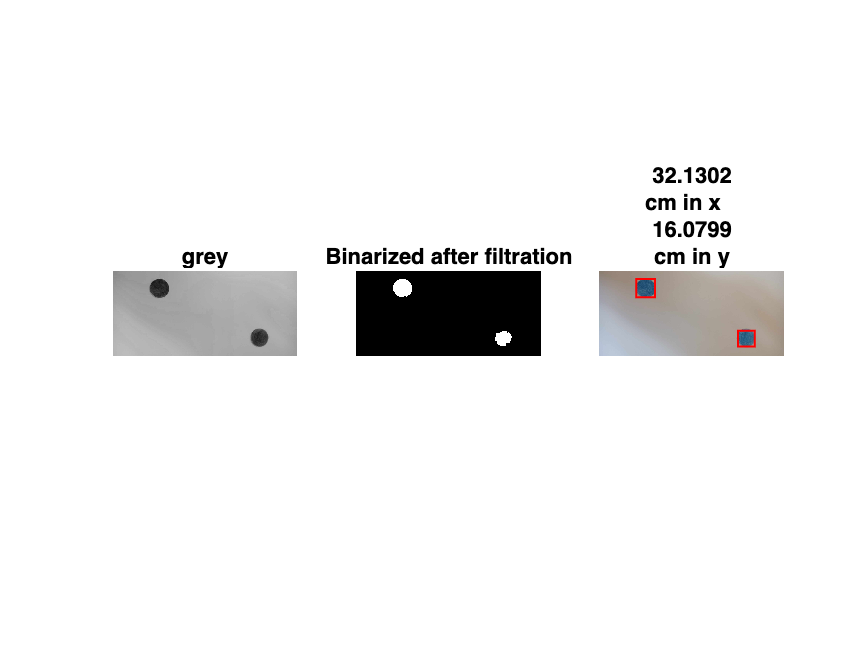

clear all
clc

A1 = imread("A1.jpg");
A2 = imread("A2.jpg");
A3 = imread("A3.jpg");
A4 = imread("A4.jpg");
B1 = imread("B1.jpg");
B2 = imread("B2.jpg");
B3 = imread("B3.jpg");



%choose photo
img = B1;

figure(2)
subplot(1,3,3)
imshow(img);

%uncomment FIRST LINE for A, and uncommand 2nd for B
%img_b = rgb2gray(img); %gray
img_b = img(:,:,1); %red



img_b = im2double(img_b);
img_p = (2*log(1+img_b));




%% IMAGE PROCESSING STUFF

bbox2 = [];
se1 = strel("square",10);  %Mask 1
se2 = strel("disk", 10); % Mask 2


level_b = graythresh(img_p);  %Level of binarization(adjust according to environment)

bin1 = imbinarize(img_p,level_b);
bin1 = imdilate(bin1,se2);
bin2 = not(bin1);%binarizing the picture
bin3 = imclose(bin2,se1);
bin4 = imdilate(bin3,se2);
%% Bounding box
bbox = regionprops(bin4,"BoundingBox","FilledArea");

%Ploting

hold on
for k = 1:length(bbox)  %Picking white areas one by one
    p = bbox(k).FilledArea;
    if p>100
    bbox2 = [bbox2;bbox(k,1)];
    BB = bbox(k).BoundingBox; 
    rectangle("Position",[BB(1),BB(2),BB(3),BB(4)],"LineWidth",1,"EdgeColor","r") %highlighting wanted area
    else
    end
end
hold off

%% Distancing 

%Framework
a = [bbox2(1).BoundingBox];
b = [bbox2(2).BoundingBox];
pixh = b(4); % height of cup in pixels (real word diameter 5cm)
ratio = 5/pixh;  %ratio of cm to pixels

%Distance between two cups

Dx = (b(1)+(b(3))/2-(a(1)+(a(3))/2))*ratio;% real distance between centres
Dy = (b(2)+(b(4))/2-(a(2)+(a(4))/2))*ratio;%calculating real distance
hold on
title([num2str(abs(Dx)), "cm in x   ",num2str(abs(Dy)), "cm in y"]);
pause(1);


subplot(1,3,2)
imshow(bin4);
title("Binarized after filtration")
subplot(1,3,1)
imshow(img_b);
title ("grey")

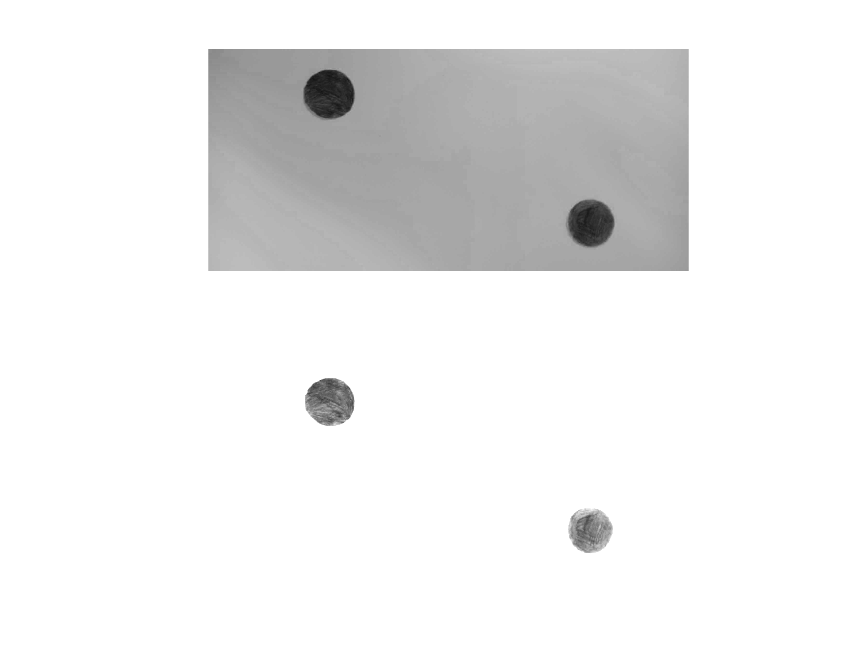



%test
figure(10)
subplot(2,1,1)
imshow(img_b);
subplot(2,1,2)
imshow(img_p);